## Set time period, database location and desired channels

dateTimeBegin           = datetime(2019, 01, 01, 'TimeZone', 'UTC');
dateTimeEnd             = datetime(2019, 06, 01, 'TimeZone', 'UTC');
hdfDataProvider         = Data.HDF.HdfDataProvider('M:\');

setenv('HDF5_VDS_PREFIX', 'M:\')

variableNameSet         = {'M0010_V2'
                           'M0070_D1' 
                           'M0390_PT_P'};
                       
datasetNameSet          = {'1 s_mean'
                           '1 s_mean_polar'
                           '1 s_mean'};

## Load data

timeSet                 = (dateTimeBegin : 1/86400 : dateTimeEnd - 1/86400).';
dataInfoSet             = hdfDataProvider.LoadDatasets('/AIRPORT/AD8_PROTOTYPE/GENERAL_DAQ', ...
                                                        variableNameSet, datasetNameSet, ....
                                                        dateTimeBegin, dateTimeEnd);

## Plot data

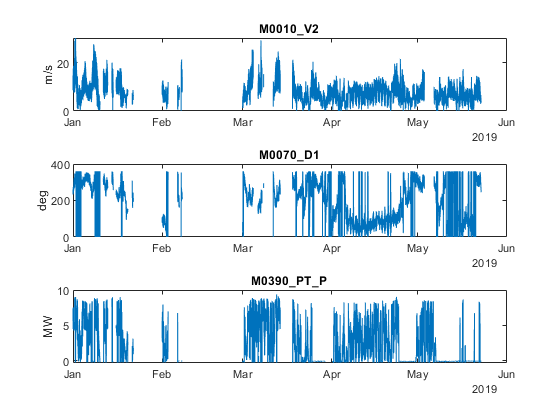

subplot(3, 1, 1)
plot(timeSet, dataInfoSet(1).Dataset);
title(strrep(dataInfoSet(1).NameSet(1), '_', '\_'));
ylabel(dataInfoSet(1).Unit);

subplot(3, 1, 2)
plot(timeSet, dataInfoSet(2).Dataset);
title(strrep(dataInfoSet(2).NameSet(1), '_', '\_'));
ylabel(dataInfoSet(2).Unit);

subplot(3, 1, 3)
plot(timeSet, dataInfoSet(3).Dataset / 1000 / 1000);
title(strrep(dataInfoSet(3).NameSet(1), '_', '\_'));
ylabel(dataInfoSet(3).Unit);